## Calculate the normalization for the probability on the detatede plane.

data "x_plot_f  y_plot_f amp_plot_f" need to be imported firstly

use less data and interpolate these data to get a function then mesh this function, get better looking figure.

x_apend = [min(x_plot_f) min(x_plot_f) max(x_plot_f) max(x_plot_f)];
y_apend = [min(y_plot_f) max(y_plot_f) min(y_plot_f) max(y_plot_f)];
amp_plot_f2 = [amp_plot_f 0 0 0 0];
x_plot_f2 = [x_plot_f x_apend];
y_plot_f2 = [y_plot_f y_apend];
F2 = TriScatteredInterp(x_plot_f2',y_plot_f2',amp_plot_f2');

% Q2 = quad2d(@(x,y) F2(x,y), min(x_plot_f),max(x_plot_f),min(y_plot_f),max(y_plot_f))

Test the interpolation 

x_grid = linspace(min(x_plot_f),max(x_plot_f),1000);
y_grid = linspace(min(y_plot_f),max(y_plot_f),1000);
[X, Y] = meshgrid(x_grid,y_grid);
AMP = F2(X,Y);

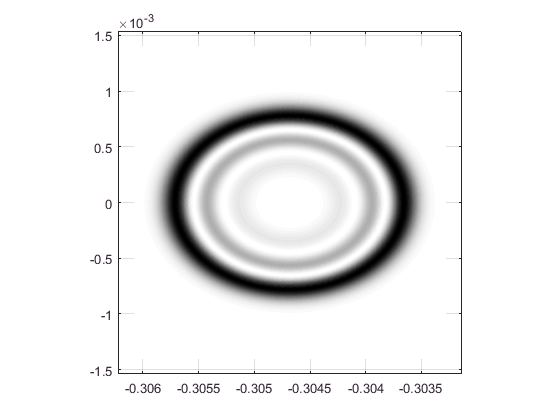

figure;
mesh(X,Y,AMP)
mapa = gray;
mapb = flipud(mapa);
colormap(mapb);
box on;
axis equal;
delta_x = x_apend(3)- x_apend(1);
delta_y = y_apend(2)-y_apend(1);
axis([x_apend(1)-1/20*delta_x x_apend(3)+1/20*delta_x y_apend(1)-1/20*delta_y y_apend(2)+1/20*delta_y])        
view(0,90)